# Clearance

close all
clear all
clc


## Variables initialisation

M1 = 5;       %[kg]
M2 = 4;       %[kg]
M3 = 5;       %[kg]

J2 = 7;       %[kg*m^2]
J3 = 6;       %[kg*m^2]

M4 = 2;       %[kg]
R = 0.8;      %[m]
r = 0.6;      %[m]

k1 = 300;     %[N/m]
k2 = 350;     %[N/m]
k3 = 50;      %[N/m]

c1 = 0.5;     %[N*s/m]
c2 = 2;       %[N*s/m]
c3 = 10;      %[N*s/m]

g = 9.81; %[m/s²]

## Question 1 : Equation of Motion and System Matrices

%%% 1.a

%syms M1 M2 M3 J2 J3 M4 R r k1 k2 k3 c1 c2 c3
%clear M1 M2 M3 J2 J3 M4 R r k1 k2 k3 c1 c2 c3


%===============================================%
%===============================================%
%===============System matrices=================% 
%===============================================%
%===============================================%

%%Kinetic energy
M_phisic = diag([M1, M2, J2, M3, J3, M4]);
JacM = [1,0,0;  1,0,0   ;  0,1,0    ;
        1,0,-r  ;   0,0,1   ;   -1,0,r];
M_star = transpose(JacM) * M_phisic * JacM

M_star =    16.0000         0   -4.2000
         0    7.0000         0
   -4.2000         0    8.5200




%Elastic potential energy
K_phisic = diag([k1,k2,k3]);
Jack = [1,0,0;0,-R,-2*r;-1,0,r];
K_star = transpose(Jack) * K_phisic * Jack

K_star =    350     0   -30
     0   224   336
   -30   336   522




% Gravitational potential energy
%P = g*[M1; M2; M3; M4]
%Lambda_y = [zeros(1,3),; zeros(1,3) ; zeros(1, 3) ; -1, 0, r ]

%_star = (P' * Lambda_y)'
%dVgdx = 0.5*P_star

C_phisic = diag([c1,c2,c3]);
C_star = transpose(Jack) * C_phisic * Jack

C_star =    10.5000         0   -6.0000
         0    1.2800    1.9200
   -6.0000    1.9200    6.4800





%===============================================%
%===============================================%
%===============Equations of Motion=============% 
%===============================================%
%===============================================%

syms x_1(t) theta_2(t) theta_3(t) F(t)


Q = [F; 0; -r*F]               %Lagrangian component of the active forces

$$Q(t) = \left(\begin{array}{c} F\left(t\right)\\ 0\\ -\frac{3\,F\left(t\right)}{5} \end{array}\right)$$



x = [x_1; theta_2; theta_3]     %Putting all the symbolic variales in a vector

$$x(t) = \left(\begin{array}{c} x_{1}\left(t\right)\\ \theta_{2}\left(t\right)\\ \theta_{3}\left(t\right) \end{array}\right)$$

dx = diff(x,t,1)                %1st derivative with respect to time

$$dx(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{3}\left(t\right) \end{array}\right)$$

ddx = diff(x,t,2)               %2nd derivative with respect to time

$$ddx(t) = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right) \end{array}\right)$$

%var = jacobian(ddx)

Mddx = M_star*ddx   %[kg.m/s²] == [N]

$$Mddx(t) = \left(\begin{array}{c} 16\,\frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)-\frac{21\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)}{5}\\ 7\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)\\ \frac{213\,\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right)}{25}-\frac{21\,\frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)}{5} \end{array}\right)$$


Cdx = C_star*dx     %[N.s/m*m/s] == [N]

$$Cdx(t) = \left(\begin{array}{c} \frac{21\,\frac{\partial }{\partial t}x_{1}\left(t\right)}{2}-6\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)\\ \frac{32\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{25}+\frac{48\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{25}\\ \frac{48\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{25}+\frac{162\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{25}-6\,\frac{\partial }{\partial t}x_{1}\left(t\right) \end{array}\right)$$


Kx = K_star*x       %[N/m.m] == [N]

$$Kx(t) = \left(\begin{array}{c} 350\,x_{1}\left(t\right)-30\,\theta_{3}\left(t\right)\\ 224\,\theta_{2}\left(t\right)+336\,\theta_{3}\left(t\right)\\ 336\,\theta_{2}\left(t\right)+522\,\theta_{3}\left(t\right)-30\,x_{1}\left(t\right) \end{array}\right)$$


Ext = Q

$$Ext(t) = \left(\begin{array}{c} F\left(t\right)\\ 0\\ -\frac{3\,F\left(t\right)}{5} \end{array}\right)$$


EoM = Mddx + Cdx + Kx; %[N]

ODESdamped = Mddx + Cdx + Kx == Q

$$ODESdamped(t) = \begin{array}{l} \left(\begin{array}{c} 350\,x_{1}\left(t\right)-30\,\theta_{3}\left(t\right)-6\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)+\frac{21\,\frac{\partial }{\partial t}x_{1}\left(t\right)}{2}-\frac{21\,\sigma_{2}}{5}+16\,\sigma_{1}=F\left(t\right)\\ 224\,\theta_{2}\left(t\right)+336\,\theta_{3}\left(t\right)+\frac{32\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{25}+\frac{48\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{25}+7\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=0\\ 336\,\theta_{2}\left(t\right)+522\,\theta_{3}\left(t\right)-30\,x_{1}\left(t\right)+\frac{48\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{25}+\frac{162\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)}{25}-6\,\frac{\partial }{\partial t}x_{1}\left(t\right)+\frac{213\,\sigma_{2}}{25}-\frac{21\,\sigma_{1}}{5}=-\frac{3\,F\left(t\right)}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right) \end{array}$$


ODESundamped = Mddx + Kx == Q

$$ODESundamped(t) = \begin{array}{l} \left(\begin{array}{c} 350\,x_{1}\left(t\right)-30\,\theta_{3}\left(t\right)-\frac{21\,\sigma_{2}}{5}+16\,\sigma_{1}=F\left(t\right)\\ 7\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)+224\,\theta_{2}\left(t\right)+336\,\theta_{3}\left(t\right)=0\\ 336\,\theta_{2}\left(t\right)+522\,\theta_{3}\left(t\right)-30\,x_{1}\left(t\right)+\frac{213\,\sigma_{2}}{25}-\frac{21\,\sigma_{1}}{5}=-\frac{3\,F\left(t\right)}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta_{3}\left(t\right) \end{array}$$

## 1.a UNDAMPED SYSTEM

[V,D] = eig(-M_star\K_star) %V => eigenvectors; D => eigenvalues lambda being the squares of w

V =     0.2487   -0.9724   -0.0439
    0.5442    0.2284    0.8364
    0.8012   -0.0473   -0.5464


D =  -102.6690         0         0
         0  -22.0654         0
         0         0   -0.6427


        %solving the equation lambda^2*x = K/M * x
        %we want to find the eigenvalues and eigenvectors of [M_star]^(-1)*[K_star] == M_star\K_star

%Extracting the natural frequencies
diagD = diag(D)

diagD =  -102.6690
  -22.0654
   -0.6427


w_nats = sqrt( diagD)   %The acquired lambdas are actually the square of the natural frequencies

w_nats =    0.0000 +10.1326i
   0.0000 + 4.6974i
   0.0000 + 0.8017i


w_nats = imag(w_nats)

w_nats =    10.1326
    4.6974
    0.8017


w_nats_ordered = sort(w_nats)   %[rad/s]

w_nats_ordered =     0.8017
    4.6974
   10.1326



%Extracting the mode shapes
mode_shapes = V ./ V(1,:) %%Normalization of mode shapes with respect to the x1_lambda = 1

mode_shapes =     1.0000    1.0000    1.0000
    2.1885   -0.2348  -19.0479
    3.2220    0.0486   12.4436


mode_shapes_und = [mode_shapes(:,3), mode_shapes(:,2), mode_shapes(:,1)]  %%mode shapes reorganization

mode_shapes_und =     1.0000    1.0000    1.0000
  -19.0479   -0.2348    2.1885
   12.4436    0.0486    3.2220


    %% We reorganize the mode shapes to match the rearrangement of the natural frequencies in increasing order
X_1 = mode_shapes_und(:,1)

X_1 =     1.0000
  -19.0479
   12.4436


X_2 = mode_shapes_und(:,2)

X_2 =     1.0000
   -0.2348
    0.0486


X_3 = mode_shapes_und(:,3)

X_3 =     1.0000
    2.1885
    3.2220


## 1.b DAMPED numcon State Space Form, eigenvalues and eigenvectors

B = [M_star, zeros(size(M_star)); zeros(size(M_star)), M_star]

B =    16.0000         0   -4.2000         0         0         0
         0    7.0000         0         0         0         0
   -4.2000         0    8.5200         0         0         0
         0         0         0   16.0000         0   -4.2000
         0         0         0         0    7.0000         0
         0         0         0   -4.2000         0    8.5200


D = [C_star, K_star; -M_star, zeros(size(M_star))]

D =    10.5000         0   -6.0000  350.0000         0  -30.0000
         0    1.2800    1.9200         0  224.0000  336.0000
   -6.0000    1.9200    6.4800  -30.0000  336.0000  522.0000
  -16.0000         0    4.2000         0         0         0
         0   -7.0000         0         0         0         0
    4.2000         0   -8.5200         0         0         0


A = (-B\D) %%State Matrix of the damped syste, we want to find the eigenvalues and eigenvectors of -[B]^(-1) * [D]

A =    -0.5415   -0.0679    0.2014  -24.0647  -11.8908  -16.3195
         0   -0.1829   -0.2743         0  -32.0000  -48.0000
    0.4373   -0.2588   -0.6613   -8.3418  -45.2983  -69.3124
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0




[Vd, Dd] = eig(-B\D)  %% Dd is diagonal, even in the case undamped D were diagonal

Vd =    0.2480 - 0.0202i   0.2480 + 0.0202i   0.9485 + 0.0000i   0.9485 + 0.0000i   0.0057 - 0.0270i   0.0057 + 0.0270i
   0.5417 - 0.0051i   0.5417 + 0.0051i  -0.2204 + 0.0767i  -0.2204 - 0.0767i  -0.0363 + 0.5224i  -0.0363 - 0.5224i
   0.7969 + 0.0000i   0.7969 + 0.0000i   0.0425 - 0.0268i   0.0425 + 0.0268i   0.0228 - 0.3414i   0.0228 + 0.3414i
  -0.0028 - 0.0244i  -0.0028 + 0.0244i  -0.0134 - 0.2017i  -0.0134 + 0.2017i  -0.0340 - 0.0048i  -0.0340 + 0.0048i
  -0.0022 - 0.0534i  -0.0022 + 0.0534i   0.0194 + 0.0458i   0.0194 - 0.0458i   0.6521 + 0.0000i   0.6521 + 0.0000i
  -0.0025 - 0.0786i  -0.0025 + 0.0786i  -0.0063 - 0.0087i  -0.0063 + 0.0087i  -0.4261 + 0.0012i  -0.4261 - 0.0012i


Dd =   -0.3257 +10.1234i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.3257 -10.1234i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.3114 + 4.6816i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.3114 - 4.6816i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0557 + 0.8010i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0557 - 0.8010i


lambdas = diag(Dd) %% for 3 Dof we have 6 lambdas

lambdas =   -0.3257 +10.1234i
  -0.3257 -10.1234i
  -0.3114 + 4.6816i
  -0.3114 - 4.6816i
  -0.0557 + 0.8010i
  -0.0557 - 0.8010i


lambdas_sorted = sort(lambdas)  %% Ordering lambdas according to the increasing natural frequencies

lambdas_sorted =   -0.0557 - 0.8010i
  -0.0557 + 0.8010i
  -0.3114 - 4.6816i
  -0.3114 + 4.6816i
  -0.3257 -10.1234i
  -0.3257 +10.1234i



Vd

Vd =    0.2480 - 0.0202i   0.2480 + 0.0202i   0.9485 + 0.0000i   0.9485 + 0.0000i   0.0057 - 0.0270i   0.0057 + 0.0270i
   0.5417 - 0.0051i   0.5417 + 0.0051i  -0.2204 + 0.0767i  -0.2204 - 0.0767i  -0.0363 + 0.5224i  -0.0363 - 0.5224i
   0.7969 + 0.0000i   0.7969 + 0.0000i   0.0425 - 0.0268i   0.0425 + 0.0268i   0.0228 - 0.3414i   0.0228 + 0.3414i
  -0.0028 - 0.0244i  -0.0028 + 0.0244i  -0.0134 - 0.2017i  -0.0134 + 0.2017i  -0.0340 - 0.0048i  -0.0340 + 0.0048i
  -0.0022 - 0.0534i  -0.0022 + 0.0534i   0.0194 + 0.0458i   0.0194 - 0.0458i   0.6521 + 0.0000i   0.6521 + 0.0000i
  -0.0025 - 0.0786i  -0.0025 + 0.0786i  -0.0063 - 0.0087i  -0.0063 + 0.0087i  -0.4261 + 0.0012i  -0.4261 - 0.0012i


X = Vd (4:6, :)   %The modes are in the lower part of the vector Vd

X =   -0.0028 - 0.0244i  -0.0028 + 0.0244i  -0.0134 - 0.2017i  -0.0134 + 0.2017i  -0.0340 - 0.0048i  -0.0340 + 0.0048i
  -0.0022 - 0.0534i  -0.0022 + 0.0534i   0.0194 + 0.0458i   0.0194 - 0.0458i   0.6521 + 0.0000i   0.6521 + 0.0000i
  -0.0025 - 0.0786i  -0.0025 + 0.0786i  -0.0063 - 0.0087i  -0.0063 + 0.0087i  -0.4261 + 0.0012i  -0.4261 - 0.0012i


normX = X./(X(1,:))  %%Normalizing with respect to the component x1 ==1

normX =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   2.1712 + 0.1567i   2.1712 - 0.1567i  -0.2323 + 0.0809i  -0.2323 - 0.0809i -18.8050 + 2.6391i -18.8050 - 2.6391i
   3.1917 + 0.2604i   3.1917 - 0.2604i   0.0448 - 0.0283i   0.0448 + 0.0283i  12.2816 - 1.7581i  12.2816 + 1.7581i


sortedX = [normX(:,5),normX(:,6), normX(:,3), normX(:,4), normX(:,1), normX(:,2)]

sortedX =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
 -18.8050 + 2.6391i -18.8050 - 2.6391i  -0.2323 + 0.0809i  -0.2323 - 0.0809i   2.1712 + 0.1567i   2.1712 - 0.1567i
  12.2816 - 1.7581i  12.2816 + 1.7581i   0.0448 - 0.0283i   0.0448 + 0.0283i   3.1917 + 0.2604i   3.1917 - 0.2604i


    %Reordering the mode shapes with respect to the increasing order of the
    %obtained frequencies : index order 5 - 6 - 3 - 4 - 1 - 2
newnormX = [sortedX(:,5), sortedX(:,3), sortedX(:,1)]   % YOU SURE ABOUT THIS ORDER?

newnormX =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   2.1712 + 0.1567i  -0.2323 + 0.0809i -18.8050 + 2.6391i
   3.1917 + 0.2604i   0.0448 - 0.0283i  12.2816 - 1.7581i


%newnormX = [sortedX(:,1), sortedX(:,3), sortedX(:,5)]  % I THINK THIS SHOULD BE THE CORRECT ORDER

absNewNormX = abs(newnormX)

absNewNormX =     1.0000    1.0000    1.0000
    2.1769    0.2460   18.9893
    3.2023    0.0530   12.4068


angleNewNormX = angle(newnormX)

angleNewNormX =          0         0         0
    0.0721    2.8065    3.0022
    0.0814   -0.5626   -0.1422



%mode_shapes_dam_abs = abs(mode_shapes_dam) .* exp(1i*angle(mode_shapes_dam))
 % angle returns in radians

%lambdas_dam_abs = abs(lambdas) .* exp(1i*angle(lambdas)) % angle returns in radians
lambdas_sorted(2:2:end)

ans =   -0.0557 + 0.8010i
  -0.3114 + 4.6816i
  -0.3257 +10.1234i


w_damped = imag(lambdas_sorted(2:2:end))

w_damped =     0.8010
    4.6816
   10.1234



alpha = -real(lambdas_sorted(2:2:end))

alpha =     0.0557
    0.3114
    0.3257




h = abs(alpha./w_damped) %%lightly damped from the results, computed from another formula

h =     0.0695
    0.0665
    0.0322


## 1.c Rayleigh Damping estimation

% Reshape the matrices into column vectors
c = C_star(:);
m = M_star(:);
k = K_star(:);

% Create a matrix A where each row is [m(i) k(i)]
G = [m k];

sol = G\c %

sol =     0.6088
    0.0026



% Extract 'a' and 'b'
a = sol(1)

a = 0.6088

b = sol(2)

b = 0.0026


C_approx = a*M_star + b * K_star

C_approx =    10.6613         0   -2.6358
         0    4.8508    0.8839
   -2.6358    0.8839    6.5601


C_star

C_star =    10.5000         0   -6.0000
         0    1.2800    1.9200
   -6.0000    1.9200    6.4800


C_diff = abs( (C_approx  - C_star) )

C_diff =     0.1613         0    3.3642
         0    3.5708    1.0361
    3.3642    1.0361    0.0801


## 2. Free motion of the system, arbitrary IC, for testing

%===============================%
% =====Initial conditions=======%
%===============================%
x_1_0       =   0.1;        %[m]
theta_2_0   =   pi/12;      %[rad]
theta_3_0   =   -pi/12;     %[rad]
v_1_0       =   1 ;         %[m/s]
v_ang_2_0   =   0.5;        %[rad/s]
v_ang_2_0   =   2;          %[rad/s]


%clear C3 C2 C1 phi_3 phi_2 phi_1
%syms  C3 C2 C1 phi_3 phi_2 phi_1

%Arbitrary for now, just for plotting purposes
C3 = -2;        %[-]
phi_3 = -3*pi;  %[rad]
C1 = 1;         %[-]
C2 = 2;         %[-]
C3 = 1;         %[-]
phi_1 = 0;      %[rad]
phi_2 = 0;      %[rad]
phi_3 = 0;      %[rad]

time_end = 70; %[s]
num_elem = time_end * 1e4;
t = linspace(0,time_end, num_elem); %[s]

x_1_t = zeros(1,num_elem);      %[m]
theta_2_t = zeros(1,num_elem);  %[rad]
theta_3_t = zeros(1,num_elem);  %[rad]

X_Free_Vibr = [ x_1_t; theta_2_t; theta_3_t];   %%Concatenating all those vectors into X
C_unkn = [C1; C2; C3]

C_unkn =      1
     2
     1



%{

%X_Free_Vibr = X_Free_Vibr + exp(-alpha(i).*t) .* abs(newnormX(:,i)) .* C3 .* cos(w_damped(:).*t + phi_3 + angle(newnormX(:,i)) );

for i = 1:3
    %%Adding the participation of each variable of interest
    disp(i)
    X_Free_Vibr = X_Free_Vibr + exp(-alpha(i).*t) .* abs(newnormX(:,i)) .* C_unkn(i) .* cos(w_damped(:).*t + phi_3 + angle(newnormX(:,i)) );
            %x_1_t = x_1_t + exp(-alpha(i)*t) .* abs(newnormX(1,i)) .* C3 .* cos(w_damped(1).*t + phi_3 + angle(newnormX(1,i)) );
            %theta_2_t = theta_2_t + exp(-alpha(i)*t) .* abs(newnormX(2,i)) .* C3 .* cos(w_damped(2).*t + phi_3 + angle(newnormX(2,i)) );
            %theta_3_t = theta_3_t + exp(-alpha(i)*t) .* abs(newnormX(3,i)) .* C3 .* cos(w_damped(3).*t + phi_3 + angle(newnormX(3,i)) );
end

X_Free_Vibr

%}

## Initial conditions, Linear system with 6 eq + 6 unknown, STILL TO FIX

syms C_1 C_2 C_3 Phi_1 Phi_2 Phi_3
C_C = [C_1; C_2; C_3];
Phi = [Phi_1; Phi_2; Phi_3];

%===============================%
% =====Initial conditions=======%
%===============================%
x_1_0       =   0.1;        %[m]
theta_2_0   =   pi/12;      %[rad]
theta_3_0   =   -pi/12;     %[rad]
v_1_0       =   1 ;         %[m/s]
v_ang_2_0   =   0.5;        %[rad/s]
v_ang_3_0   =   2;          %[rad/s]

% Define the equations
eq_cond_x_1     = sum((C_C .* absNewNormX(1,:)') .* cos(Phi + angleNewNormX(1,:)')) == x_1_0

$$eq\_cond\_x\_1 = C_{1}\,\cos\left(\Phi_{1}\right)+C_{2}\,\cos\left(\Phi_{2}\right)+C_{3}\,\cos\left(\Phi_{3}\right)=\frac{1}{10}$$

eq_cond_theta_2 = sum((C_C .* absNewNormX(2,:)') .* cos(Phi + angleNewNormX(2,:)')) == theta_2_0

$$eq\_cond\_theta\_2 = \frac{4901924296910687\,C_{1}\,\cos\left(\Phi_{1}+\frac{2596463732872441}{36028797018963968}\right)}{2251799813685248}+\frac{2215917559648199\,C_{2}\,\cos\left(\Phi_{2}+\frac{6319741833370221}{2251799813685248}\right)}{9007199254740992}+\frac{5345020887469603\,C_{3}\,\cos\left(\Phi_{3}+\frac{6760270012660601}{2251799813685248}\right)}{281474976710656}=\frac{\pi }{12}$$

eq_cond_theta_3 = sum((C_C .* absNewNormX(3,:)') .* cos(Phi + angleNewNormX(3,:)')) == theta_3_0

$$eq\_cond\_theta\_3 = \frac{1910210710385409\,C_{2}\,\cos\left(\Phi_{2}-\frac{1266828259271581}{2251799813685248}\right)}{36028797018963968}+\frac{901356901096913\,C_{1}\,\cos\left(\Phi_{1}+\frac{2933453089654753}{36028797018963968}\right)}{281474976710656}+\frac{6984389378930435\,C_{3}\,\cos\left(\Phi_{3}-\frac{2561317537478021}{18014398509481984}\right)}{562949953421312}=-\frac{\pi }{12}$$


%shift = (atan(mod(w_damped ./ alpha, pi)));
shift = atan (w_damped ./ alpha)

shift =     1.5014
    1.5044
    1.5386



eq_cond_v_1     = sum((C_C .* absNewNormX(1,:)') .* cos(Phi + angleNewNormX(1,:)' - shift)) == - v_1_0

$$eq\_cond\_v\_1 = C_{1}\,\cos\left(\Phi_{1}-\frac{3380832261880247}{2251799813685248}\right)+C_{2}\,\cos\left(\Phi_{2}-\frac{6775127056085589}{4503599627370496}\right)+C_{3}\,\cos\left(\Phi_{3}-\frac{6929385217410971}{4503599627370496}\right)=-1$$

eq_cond_v_ang_2 = sum((C_C .* absNewNormX(2,:)') .* cos(Phi + angleNewNormX(2,:)' - shift)) == - v_ang_2_0

$$eq\_cond\_v\_ang\_2 = \frac{4901924296910687\,C_{1}\,\cos\left(\Phi_{1}-\frac{51496852457211511}{36028797018963968}\right)}{2251799813685248}+\frac{5345020887469603\,C_{3}\,\cos\left(\Phi_{3}+\frac{6591154807910231}{4503599627370496}\right)}{281474976710656}+\frac{2215917559648199\,C_{2}\,\cos\left(\Phi_{2}+\frac{5864356610654853}{4503599627370496}\right)}{9007199254740992}=-\frac{1}{2}$$

eq_cond_v_ang_3 = sum((C_C .* absNewNormX(3,:)') .* cos(Phi + angleNewNormX(3,:)' - shift)) == - v_ang_3_0

$$eq\_cond\_v\_ang\_3 = \frac{901356901096913\,C_{1}\,\cos\left(\Phi_{1}-\frac{51159863100429199}{36028797018963968}\right)}{281474976710656}+\frac{1910210710385409\,C_{2}\,\cos\left(\Phi_{2}-\frac{9308783574628751}{4503599627370496}\right)}{36028797018963968}+\frac{6984389378930435\,C_{3}\,\cos\left(\Phi_{3}-\frac{30278858407121905}{18014398509481984}\right)}{562949953421312}=-2$$


% Simplify equations
eq_cond_x_1     = simplify(eq_cond_x_1)

$$eq\_cond\_x\_1 = C_{1}\,\cos\left(\Phi_{1}\right)+C_{2}\,\cos\left(\Phi_{2}\right)+C_{3}\,\cos\left(\Phi_{3}\right)=\frac{1}{10}$$

eq_cond_theta_2 = simplify(eq_cond_theta_2)

$$eq\_cond\_theta\_2 = 58823091562928244\,C_{1}\,\cos\left(\Phi_{1}+\frac{2596463732872441}{36028797018963968}\right)+6647752678944597\,C_{2}\,\cos\left(\Phi_{2}+\frac{6319741833370221}{2251799813685248}\right)+513122005197081888\,C_{3}\,\cos\left(\Phi_{3}+\frac{6760270012660601}{2251799813685248}\right)=2251799813685248\,\pi$$

eq_cond_theta_3 = simplify(eq_cond_theta_3)

$$eq\_cond\_theta\_3 = 5730632131156227\,C_{2}\,\cos\left(\Phi_{2}-\frac{1266828259271581}{2251799813685248}\right)+346121050021214592\,C_{1}\,\cos\left(\Phi_{1}+\frac{2933453089654753}{36028797018963968}\right)+1341002760754643520\,C_{3}\,\cos\left(\Phi_{3}-\frac{2561317537478021}{18014398509481984}\right)=-9007199254740992\,\pi$$

eq_cond_v_1     = simplify(eq_cond_v_1)

$$eq\_cond\_v\_1 = C_{1}\,\cos\left(\Phi_{1}-\frac{3380832261880247}{2251799813685248}\right)+C_{2}\,\cos\left(\Phi_{2}-\frac{6775127056085589}{4503599627370496}\right)+C_{3}\,\cos\left(\Phi_{3}-\frac{6929385217410971}{4503599627370496}\right)=-1$$

eq_cond_v_ang_2 = simplify(eq_cond_v_ang_2)

$$eq\_cond\_v\_ang\_2 = 19607697187642748\,C_{1}\,\cos\left(\Phi_{1}-\frac{51496852457211511}{36028797018963968}\right)+171040668399027296\,C_{3}\,\cos\left(\Phi_{3}+\frac{6591154807910231}{4503599627370496}\right)+2215917559648199\,C_{2}\,\cos\left(\Phi_{2}+\frac{5864356610654853}{4503599627370496}\right)=-4503599627370496$$

eq_cond_v_ang_3 = simplify(eq_cond_v_ang_3)

$$eq\_cond\_v\_ang\_3 = 115373683340404864\,C_{1}\,\cos\left(\Phi_{1}-\frac{51159863100429199}{36028797018963968}\right)+1910210710385409\,C_{2}\,\cos\left(\Phi_{2}-\frac{9308783574628751}{4503599627370496}\right)+447000920251547840\,C_{3}\,\cos\left(\Phi_{3}-\frac{30278858407121905}{18014398509481984}\right)=-72057594037927936$$


eq_bundle = [eq_cond_x_1, eq_cond_theta_2, eq_cond_theta_3, eq_cond_v_1, eq_cond_v_ang_2, eq_cond_v_ang_3];


% Solve numerically
sol = vpasolve(eq_bundle, [C_1, C_2, C_3, Phi_1, Phi_2, Phi_3])

sol = struct with fields:
      C_1: -0.5151852623639829230349268213483
      C_2: 0.49967729414144253943954031802799
      C_3: -0.030479347673051972343969088087314
    Phi_1: 7.740537294654663784513785793373
    Phi_2: -7.5049064449077802973822053471868
    Phi_3: 1.1451752220942293834664129292483



c_1 = double(sol.C_1)

c_1 = -0.5152

c_2 = double(sol.C_2)

c_2 = 0.4997

c_3 = double(sol.C_3)

c_3 = -0.0305

myC = [c_1; c_2; c_3]

myC =    -0.5152
    0.4997
   -0.0305


phi_1 = double(sol.Phi_1)

phi_1 = 7.7405

phi_2 = double(sol.Phi_2)

phi_2 = -7.5049

phi_3 = double(sol.Phi_3)

phi_3 = 1.1452

myPhi = [phi_1; phi_2; phi_3]

myPhi =     7.7405
   -7.5049
    1.1452



X_1_w_d_1 = exp(-alpha(1).*t) .* abs(newnormX(:,1)) .* myC .* cos(w_damped(:).*t + myPhi + angle(newnormX(:,1)) )

X_1_w_d_1 =    -0.0583   -0.0583   -0.0582   -0.0582   -0.0582   -0.0581   -0.0581   -0.0580   -0.0580   -0.0579   -0.0579   -0.0579   -0.0578   -0.0578   -0.0577   -0.0577   -0.0577   -0.0576   -0.0576   -0.0575   -0.0575   -0.0575   -0.0574   -0.0574   -0.0573   -0.0573   -0.0572   -0.0572   -0.0572   -0.0571   -0.0571   -0.0570   -0.0570   -0.0570   -0.0569   -0.0569   -0.0568   -0.0568   -0.0567   -0.0567   -0.0567   -0.0566   -0.0566   -0.0565   -0.0565   -0.0565   -0.0564   -0.0564   -0.0563   -0.0563
    0.4447    0.4451    0.4456    0.4461    0.4465    0.4470    0.4474    0.4479    0.4484    0.4488    0.4493    0.4498    0.4502    0.4507    0.4511    0.4516    0.4521    0.4525    0.4530    0.4534    0.4539    0.4544    0.4548    0.4553    0.4557    0.4562    0.4567    0.4571    0.4576    0.4580    0.4585    0.4590    0.4594    0.4599    0.4603    0.4608    0.4612    0.4617    0.4622    0.4626    0.4631    0.4635    0.4640    0.4645    0.4649    0.4654    0.4658    0.4663    0.4

X_1_w_d_2 = exp(-alpha(2).*t) .* abs(newnormX(:,2)) .* myC .* cos(w_damped(:).*t + myPhi + angle(newnormX(:,2)) )

X_1_w_d_2 =    -0.0583   -0.0583   -0.0582   -0.0582   -0.0581   -0.0581   -0.0581   -0.0580   -0.0580   -0.0579   -0.0579   -0.0578   -0.0578   -0.0578   -0.0577   -0.0577   -0.0576   -0.0576   -0.0575   -0.0575   -0.0575   -0.0574   -0.0574   -0.0573   -0.0573   -0.0572   -0.0572   -0.0572   -0.0571   -0.0571   -0.0570   -0.0570   -0.0570   -0.0569   -0.0569   -0.0568   -0.0568   -0.0567   -0.0567   -0.0567   -0.0566   -0.0566   -0.0565   -0.0565   -0.0564   -0.0564   -0.0564   -0.0563   -0.0563   -0.0562
   -0.0017   -0.0018   -0.0018   -0.0019   -0.0020   -0.0020   -0.0021   -0.0021   -0.0022   -0.0022   -0.0023   -0.0024   -0.0024   -0.0025   -0.0025   -0.0026   -0.0026   -0.0027   -0.0028   -0.0028   -0.0029   -0.0029   -0.0030   -0.0030   -0.0031   -0.0032   -0.0032   -0.0033   -0.0033   -0.0034   -0.0034   -0.0035   -0.0036   -0.0036   -0.0037   -0.0037   -0.0038   -0.0038   -0.0039   -0.0040   -0.0040   -0.0041   -0.0041   -0.0042   -0.0042   -0.0043   -0.0044   -0.0044   -0.0

X_1_w_d_3 = exp(-alpha(3).*t) .* abs(newnormX(:,3)) .* myC .* cos(w_damped(:).*t + myPhi + angle(newnormX(:,3)) )

X_1_w_d_3 =    -0.0583   -0.0583   -0.0582   -0.0582   -0.0581   -0.0581   -0.0581   -0.0580   -0.0580   -0.0579   -0.0579   -0.0578   -0.0578   -0.0578   -0.0577   -0.0577   -0.0576   -0.0576   -0.0575   -0.0575   -0.0575   -0.0574   -0.0574   -0.0573   -0.0573   -0.0572   -0.0572   -0.0572   -0.0571   -0.0571   -0.0570   -0.0570   -0.0569   -0.0569   -0.0569   -0.0568   -0.0568   -0.0567   -0.0567   -0.0566   -0.0566   -0.0566   -0.0565   -0.0565   -0.0564   -0.0564   -0.0563   -0.0563   -0.0563   -0.0562
   -1.9747   -1.9790   -1.9832   -1.9875   -1.9918   -1.9961   -2.0004   -2.0046   -2.0089   -2.0132   -2.0175   -2.0217   -2.0260   -2.0303   -2.0345   -2.0388   -2.0431   -2.0474   -2.0516   -2.0559   -2.0602   -2.0644   -2.0687   -2.0730   -2.0772   -2.0815   -2.0857   -2.0900   -2.0943   -2.0985   -2.1028   -2.1070   -2.1113   -2.1156   -2.1198   -2.1241   -2.1283   -2.1326   -2.1368   -2.1411   -2.1453   -2.1496   -2.1538   -2.1581   -2.1623   -2.1666   -2.1708   -2.1751   -2.1


myFreeVibr = X_1_w_d_1 + X_1_w_d_2 + X_1_w_d_3;


## Plots

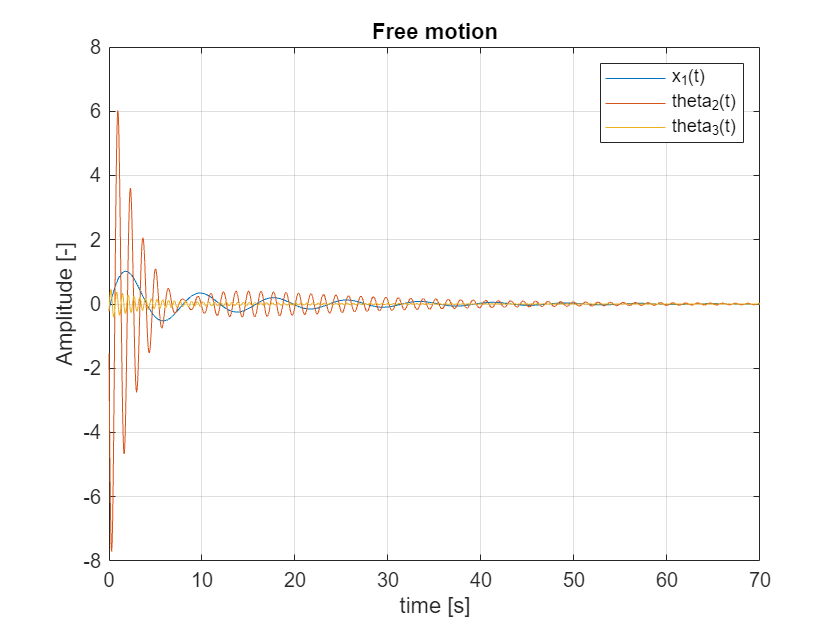

% Overlapped Plots
figure()
plot(t,myFreeVibr)
titleStr = "Free motion";
title(titleStr);
grid on;
ylabel("Amplitude [-]");
xlabel("time [s]");
legend("x_1(t)", "theta_2(t)", "theta_3(t)");

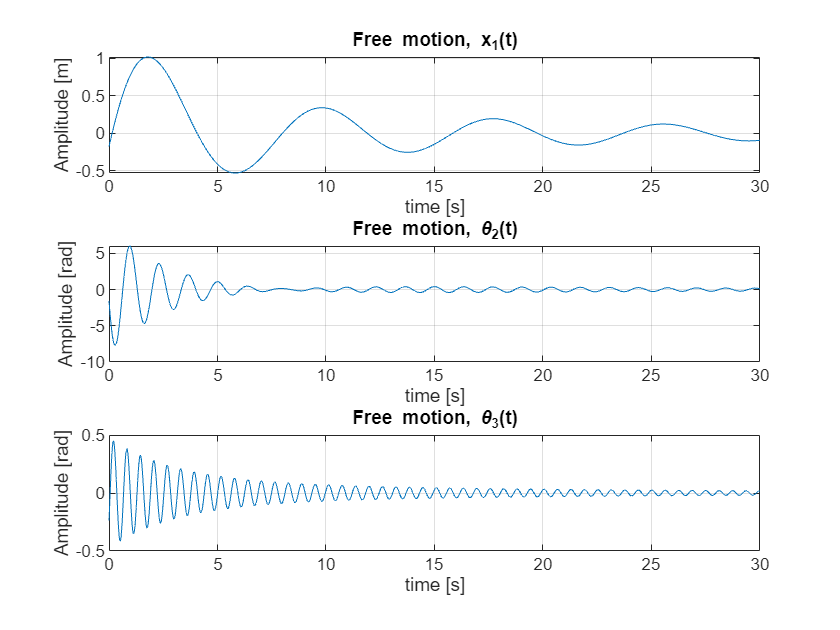



% Separate Plots
figure();
subplot(3,1,1);
plot(t,myFreeVibr(1,:))
titleStr = "Free motion, x_1(t)";
title(titleStr);
grid on;
ylabel("Amplitude [m]");
xlabel("time [s]");
xlim([0, 30]);
%ylim([-1.1, 1.1]);

subplot(3,1,2);
plot(t,myFreeVibr(2,: ))
titleStr = "Free motion, \theta_2(t)";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("time [s]");
xlim([0, 30]);
%ylim([-8, 8]);

subplot(3,1,3);
plot(t,myFreeVibr(3,: ))
titleStr = "Free motion, \theta_3(t)";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("time [s]");
xlim([0, 30]);

%ylim([-0.5, 0.5]);

## Plots

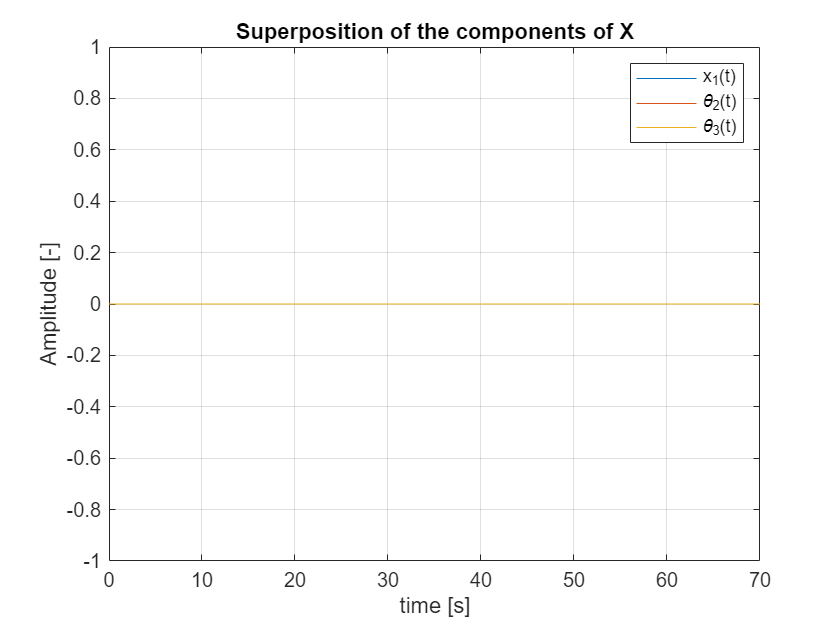


% Overlapped plots
figure()
for i = 1:3
    plot(t,X_Free_Vibr(i,:))
    titleStr = "Superposition of the components of X";
    title(titleStr);
    hold on;
    
    grid on;
end
ylabel("Amplitude [-]");
xlabel("time [s]");
legend("x_1(t)", "\theta_2(t)", "\theta_3(t)");

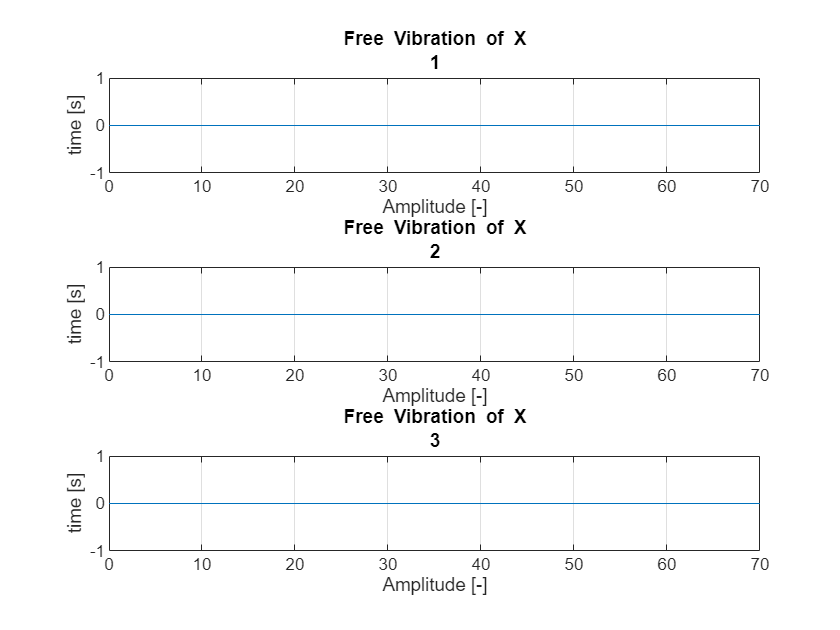



% Non overlapped plots
figure()
for i = 1:3
    subplot(3,1,i);
    plot(t,X_Free_Vibr(i,:));
    titleStr = [ "Free Vibration of X_", i];
    xlabel("Amplitude [-]");
    ylabel("time [s]");
    grid on;
    title(titleStr);
end

# Manual calculations

% alpha_i, C_i, omgea_d_i and phi_i
alfa = alpha'

alfa =     0.0557    0.3114    0.3257


const = myC'

const =    -0.5152    0.4997   -0.0305


omega_d = w_damped'

omega_d =     0.8010    4.6816   10.1234


phase = myPhi'

phase =     7.7405   -7.5049    1.1452


%phase = wrapTo2Pi(myPhi')

## Explicit formulation x_1

x_1 = 0;
% Eigenvector entries abs and angle
amplitude = abs([sortedX(1,1), sortedX(1,3), sortedX(1,5)])     % first row of newnormX of row 126

amplitude =      1     1     1


shift = angle([sortedX(1,1), sortedX(1,3), sortedX(1,5)])

shift =      0     0     0


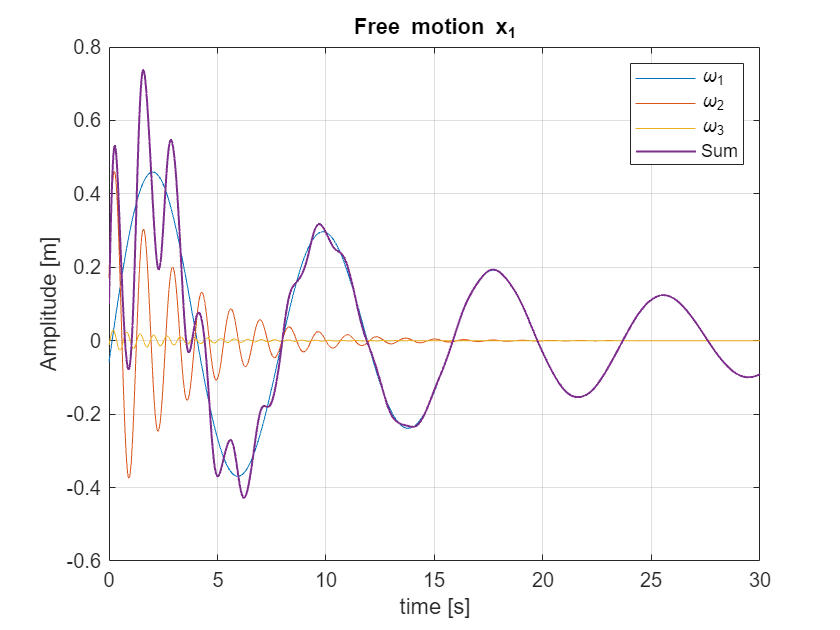


t = linspace(0, 70, 70*1e4);

figure()

for i = 1:3
    x_1 = x_1 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, x_1, LineWidth = 1)
titleStr = "Free motion x_1";
title(titleStr);
grid on;
ylabel("Amplitude [m]");
xlabel("time [s]");
xlim([0, 30]);
legend("\omega_1", "\omega_2", "\omega_3", "Sum");

## Explicit formulation theta_2

theta_2 = 0;
% Eigenvector entries abs and angle
amplitude = abs([sortedX(2,1), sortedX(2,3), sortedX(2,5)])         % second row of newnormX of row 126

amplitude =    18.9893    0.2460    2.1769


shift = angle([sortedX(2,1), sortedX(2,3), sortedX(2,5)])

shift = 1×3
    3.0022    2.8065    0.0721


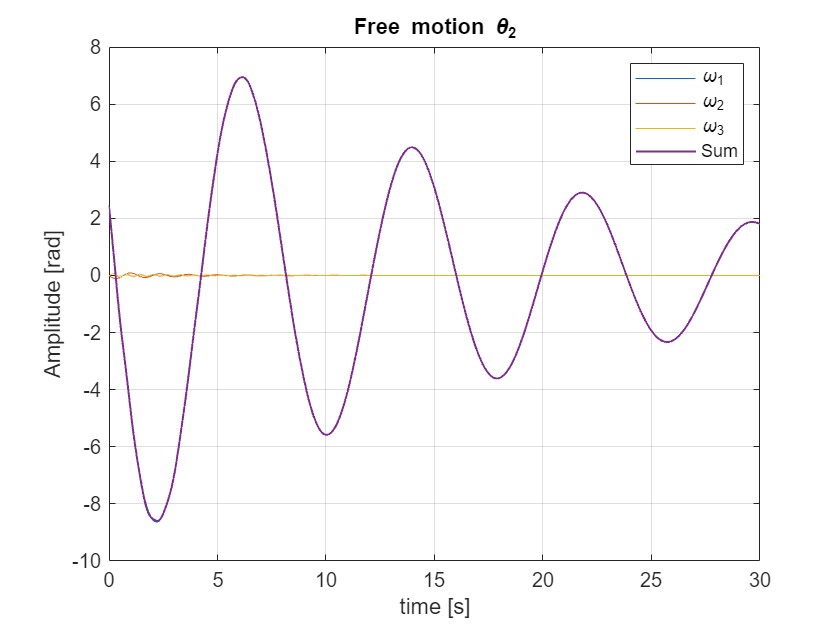


t = linspace(0, 70, 70*1e4);

figure()

for i = 1:3
    theta_2 = theta_2 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, theta_2, LineWidth = 1)
titleStr = "Free motion \theta_2";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("time [s]");
xlim([0, 30]);
legend("\omega_1", "\omega_2", "\omega_3", "Sum");

## Explicit formulation theta_3

theta_3 = 0;
% Eigenvector entries abs and angle
amplitude = abs([sortedX(3,1), sortedX(3,3), sortedX(3,5)])         % third row of newnormX of row 126

amplitude = 1×3
   12.4068    0.0530    3.2023


shift = angle([sortedX(3,1), sortedX(3,3), sortedX(3,5)])

shift = 1×3
   -0.1422   -0.5626    0.0814


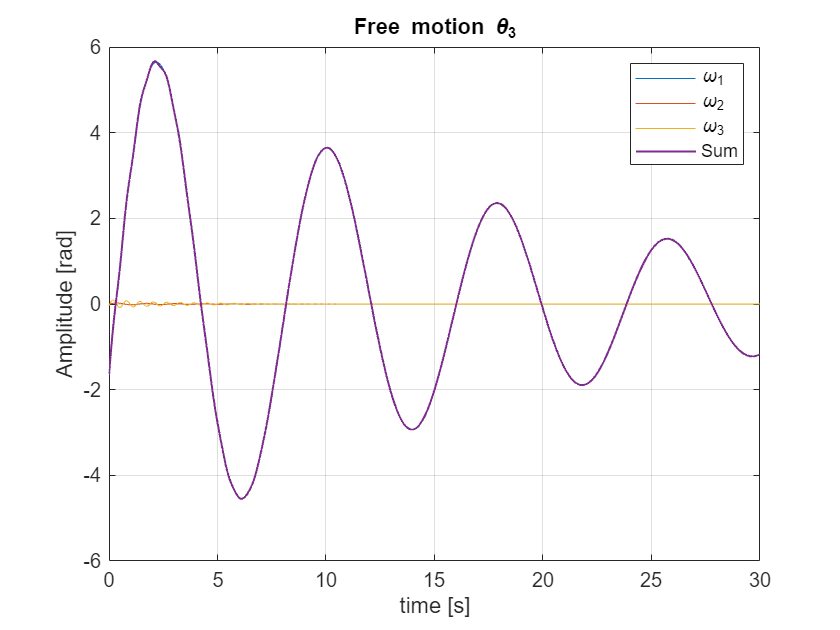


t = linspace(0, 70, 70*1e4);

figure()

for i = 1:3
    theta_3 = theta_3 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, theta_3, LineWidth = 1)
titleStr = "Free motion \theta_3";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("time [s]");
xlim([0, 30]);
legend("\omega_1", "\omega_2", "\omega_3", "Sum");

## Plotting all together

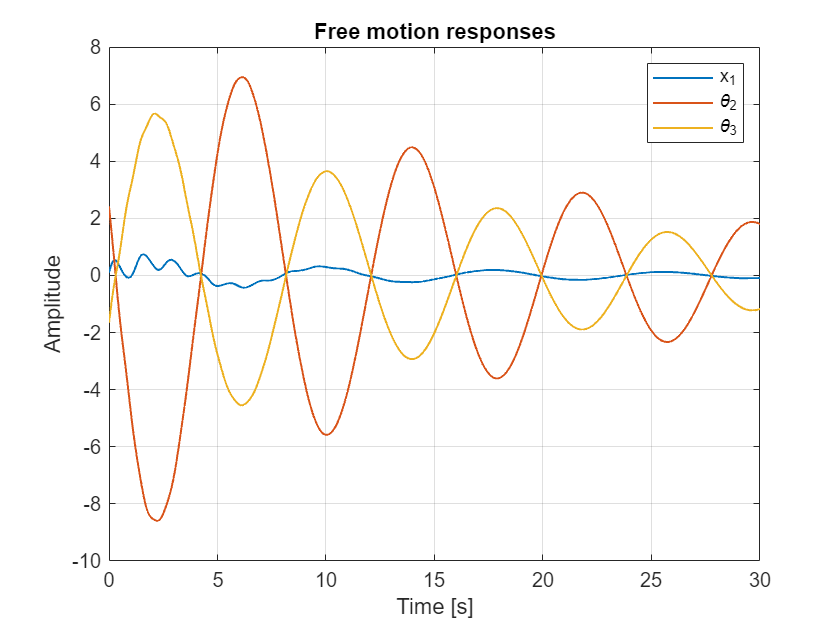

figure()
plot(t, x_1, LineWidth = 1)
hold on;
plot(t, theta_2, LineWidth = 1)
plot(t, theta_3, LineWidth = 1)
grid on;
titleStr = "Free motion responses";
title(titleStr);
ylabel("Amplitude");
xlabel("Time [s]");
xlim([0, 30]);
legend("x_1", "\theta_2", "\theta_3");